## Taller 4

## Punto 4

% i) Calculando los retornos de las TRMs,
clc; clear all; close all;

% === Importar los datos ===
ds = readtable("TRM.xlsx", "Sheet", "TRM2", "UseExcel", false);

%Estimando los retornos mensuales de la TRM,
vars= ds.Properties.VariableNames;

for i = 2:length(vars) 
    oldvar = vars{i};

    % Reemplazar la variable original con su retorno logarítmico en porcentaje
    ds.(oldvar) = [NaN; diff(log(ds.(oldvar)))] * 100;
end

writetable(ds, 'TRM_retornos.xlsx');

% ii) Estandarizando los retornos,
vars2= ds.Properties.VariableNames;

for i = 1:length(vars2) 
    nutria = vars2{i};

    %Sacando las estadísticas necesarias,
    media = mean(ds.(nutria), 'omitnan');
    desv = std(ds.(nutria), 'omitnan');

    %Creando la var estandarizada,
    chancho = ['z_' nutria]; 

    % Cálculo del retorno logarítmico multiplicado por 100 (porcentaje)
    ds.(chancho) = (ds.(nutria) - media) / desv;
end

%Quedándonos con las variables relevantes,
vars4= ds.Properties.VariableNames;
vars5 = vars4(startsWith(vars4, 'z'));
vars_keep = [{'Fecha'}, vars5]; 
ds = ds(:, vars_keep);

ds.z_Fecha = [];


writetable(ds, 'TRM_estandarizada.xlsx');

% v) Haciendo la reducción tipo Lasso,
%Definiendo las vars exógenas y las endógenas, 
Y= ds.z_Colombia %Endógena

Y =        NaN
   -0.1664
   -0.4549
    0.3981
    1.2260
    0.9085
    2.1749
    0.9077
    1.5407
   -0.0563


    
    %Eliminando la fila de NaNs,
    Y = Y(2:end, :);

x = ds(:, 3:end); %Exógenas
X = table2array(x); %Exógenas

    %Eliminando la fila de NaNs,
    X = X(2:end, :);

% Usemos el algoritmo que tiene MATLAB para seleccionar el modelo

[BL StatsL] = lasso(X,Y, 'CV', 10,'intercept',false);

disp(BL)

   -0.1207   -0.1207   -0.1206   -0.1206   -0.1205   -0.1205   -0.1203   -0.1203   -0.1201   -0.1201   -0.1199   -0.1198   -0.1196   -0.1196   -0.1190   -0.1187   -0.1184   -0.1180   -0.1176   -0.1172   -0.1167   -0.1162   -0.1156   -0.1150   -0.1143   -0.1135   -0.1127   -0.1117   -0.1107   -0.1098   -0.1088   -0.1077   -0.1066   -0.1053   -0.1039   -0.1023   -0.1008   -0.0992   -0.0974   -0.0956   -0.0934   -0.0912   -0.0885   -0.0874   -0.0862   -0.0849   -0.0836   -0.0823   -0.0810   -0.0795   -0.0781   -0.0765   -0.0749   -0.0733   -0.0717   -0.0702   -0.0687   -0.0672   -0.0655   -0.0641   -0.0621   -0.0594   -0.0568   -0.0540   -0.0510   -0.0476   -0.0439   -0.0398   -0.0353   -0.0305   -0.0242   -0.0197   -0.0152   -0.0104   -0.0046         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

disp(StatsL)

         Intercept: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
            Lambda: [5.3969e-05 5.9231e-05 6.5006e-05 7.1344e-05 7.8300e-05 8.5934e-05 9.4312e-05 1.0351e-04 1.1360e-04 1.2468e-04 1.3683e-04 1.5017e-04 1.6481e-04 1.8088e-04 1.9852e-04 2.1787e-04 2.3912e-04 2.6243e-04 2.8802e-04 … ] (1×100 double)
             Alpha: 1
                DF: [96 95 92 94 93 92 94 93 93 92 94 95 94 91 91 92 91 91 91 93 92 93 92 92 92 93 91 94 94 93 91 91 92 92 90 90 90 91 87 88 89 84 83 81 80 74 74 72 72 69 71 69 73 67 63 63 62 62 60 55 52 48 48 47 46 44 40 38 33 32 31 … ] (1×100 double)
               MSE: [0.9994 0.9991 0.9989 0.9986 0.9980 0.9969 0.9966 0.9960 0.9957 0.9944 0.9935 0.9930 0.9917 0.9908 0.9896 0.9885 0.9867 0.9852 0.9841 0.9821 0.9804 0.9780 0.9760 0.9731 0.9705 0.9679 0.9636 0.9613 0.9574 0.9539 … ] (1×100 double)
    

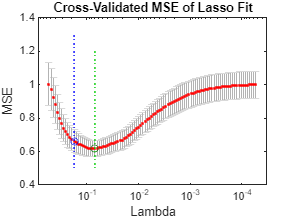


% Calcular el valor máximo de Lambda
max_lambda = max(abs(X' * Y)) / size(X, 1);

% Creemos una gráfica donde se muestre el error cuadrado medio y los 
% Lambda estimados.

lassoPlot(BL, StatsL, 'PlotType', 'CV')


% Identifiquemos los betas con el lambda asociado a la menor reducción posible
% indice: IndexMinMSE
BLasso = BL(:,StatsL.Index1SE)

BLasso =          0
         0
         0
    0.0109
         0
         0
         0
         0
         0
         0


%Viendo a qué variables corresponden los coeficientes diferentes a 0,
varNames = x.Properties.VariableNames;
selectedVars = varNames(BLasso ~= 0);

Vars_elegidas = table(varNames', BLasso, 'VariableNames', {'Variable', 'Coefficient'});
disp(Vars_elegidas)

                                Variable                                 Coefficient
    _________________________________________________________________    ___________

    {'z_Guyana'                                                     }             0 
    {'z_Haiti'                                                      }             0 
    {'z_SolomonIslands'                                             }             0 
    {'z_Uruguay'                                                    }      0.010905 
    {'z_Nicaragua'                                                  }             0 
    {'z_Libya'                                                      }             0 
    {'z_Israel'                                                     }             0 
    {'z_TaiwanProvinceOfChina'                                      }             0 
    {'z_CaboVerde'                                                  }            

% vi) Estimando el primer componente principal,

    %Primero, filtramos la base de datos para solo mostrar las vars
    %elegidas por Lasso,
    ds_lasso= ds(2:end, selectedVars)

ds_lasso = 311×9 table
    z_Uruguay    z_Mexico    z_Korea_RepublicOf    z_Brazil    z_Chile     z_Kiribati    z_NewZealand    z_Kazakhstan_RepublicOf    z_Vanuatu
    _________    ________    __________________    ________    ________    __________    ____________    _______________________    _________

     -0.19526     -0.4403           0.3476            5.901      1.2679     -0.52807       -0.33914               0.10824           0.0090818
      0.30034     -1.0175            1.551         -0.33168    -0.15842      0.57389        0.82544               0.40067             0.59032
    -0.027777     -1.3489         -0.77599          -2.9168    -0.85446     -0.68123       -0.69764   

%Hallamos el factor,
lasso_bonito= table2array(ds_lasso)

lasso_bonito =    -0.1953   -0.4403    0.3476    5.9010    1.2679   -0.5281   -0.3391    0.1082    0.0091
    0.3003   -1.0175    1.5510   -0.3317   -0.1584    0.5739    0.8254    0.4007    0.5903
   -0.0278   -1.3489   -0.7760   -2.9168   -0.8545   -0.6812   -0.6976    7.7785   -0.1347
   -0.0283   -0.4187   -0.4759   -0.2669    0.1210   -1.1447   -0.6544    1.8981   -0.3950
    0.2489    0.6299   -1.0708    1.0671    1.1953    0.3474    1.3354    2.8970    0.3741
    0.3994   -0.7786    0.5991    0.3739    0.9699   -0.1032    0.4122    0.2636    0.0601
    0.2730    0.0403    0.4907    0.9729   -0.3517    0.7045   -0.0178   -0.2496   -0.1743
    0.1493   -0.3158   -0.1347    0.1161    0.7339   -0.1961    0.3270    0.5988   -0.1751
   -0.5020    0.7126    0.3242    0.8047    0.9035   -0.1538    0.5337    1.1322   -0.2368
   -0.2271   -0.5589   -1.1311   -0.6161    0.2436    0.6819    0.1761   -0.4715    0.4542


C = cov(lasso_bonito);
[A,PC,EigValue, ~, Exp] = pca(lasso_bonito);
PC1=PC(:,1);
factor2=PC1(:,1)./sqrt(EigValue(1,1));
% % de la varianza explicada:
P_VExplicada= EigValue/sum(EigValue)*100;

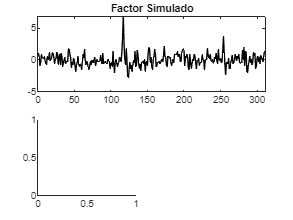

figure ()

subplot(2,1,1)
plot(factor2,'Color','k')
title('Factor Simulado')

subplot(2,2,3)

plot(Vars_elegidas)

Error using plot
Invalid number of input arguments. Specify one or two table subscripts after the table.

title('Variables Simuladas Para Estimar Factor')

subplot(2,2,4)
plot(factor2(1:20))
hold on
plot(factor2(1:20))
legend('Factor Simulado','Factor Estimado Con PC','Location','NorthEast')
title('Factor Estimado vs. Componente Principal')

% Hallando el coeficiente de correlación del factor estimado y los retornos
% de la TMR en Colombia,
TRM_Colombia = ds.z_Colombia;  % Retornos estandarizados de la TRM

corr_factor_TRM = corr(factor2, TRM_Colombia(2:end));  % Correlación
disp(corr_factor_TRM);

    0.6611



%% vii) Estimando los modelos, (CON RETORNOS SIN ESTANDARIZAR)
%Generando la base sin estandarizar otra vez,
ds_estimar = readtable("TRM.xlsx", "Sheet", "TRM2", "UseExcel", false);

%Estimando los retornos mensuales de la TRM,
vars_est= ds_estimar.Properties.VariableNames;

for i = 2:length(vars_est) 
    oldvar_est = vars_est{i};

    % Reemplazar la variable original con su retorno logarítmico en porcentaje
    ds_estimar.(oldvar_est) = [NaN; diff(log(ds_estimar.(oldvar_est)))] * 100;
end

ds_estimar = ds_estimar(2:end, :)

ds_estimar = 311×120 table
       Fecha       Colombia     Guyana        Haiti      SolomonIslands    Uruguay     Nicaragua     Libya       Israel     TaiwanProvinceOfChina    CaboVerde    Mozambique_RepublicOf    Seychelles      Kenya      Philippines     Rwanda      Angola     Bolivia    Denmark     EuroArea_EA_    Comoros_UnionOfThe      Sweden       WestAfricanEconomicAndMonetaryUnion_WAEMU_     Benin      Senegal      Niger      Cameroon    Guinea_Bissau    FrenchPolynesia      Togo

% Estimemos diferentes modelos autoregresivos y guardemos sus criterios de
% información AIC y BIC para ver cual es el mejor:

%  Definir orden máximo de AR y MA
AR = 5; % Máximo orden AR
MA = 5; % Máximo orden MA

% Inicializar matrices de almacenamiento
LL = NaN(AR+1, MA+1);   % Log-Likelihood
NBetas = NaN(AR+1, MA+1); % Número de parámetros


% Estimación de modelos ARIMA(p,1,q)
for i = 0:AR
    for j = 0:MA
        Mdl = arima(i,0,j); % Definir modelo ARIMA(p,0,q) (0 porque ya diferenciamos la serie antes)
        try
            [EstMdl,~,Logl] = estimate(Mdl, ds_estimar.Colombia, 'Display', 'off');
            LL(i+1, j+1) = Logl; % Guardar Log-Likelihood
            NBetas(i+1, j+1) = i + j + 1; % Número de parámetros (p + q + 1)
        catch
            % Si la estimación falla, deja NaN
            continue;
        end
    end
end

% Calcular criterios AIC y BIC
T = sum(~isnan(ds_estimar.Colombia)); % Número de observaciones sin NaN
AIK = NaN(size(LL));

Unrecognized function or variable 'LL'.

SIC = NaN(size(LL));

for j = 1:(MA+1)
    valid_idx = ~isnan(LL(:, j));
    if any(valid_idx)
        [aic, bic] = aicbic(LL(valid_idx, j), NBetas(valid_idx, j), T);
        AIK(valid_idx, j) = aic;
        SIC(valid_idx, j) = bic;
    end
end

% Encontrar modelos óptimos según AIC y BIC
[~, minAIC_idx] = min(AIK(:), [], 'omitnan');
[~, minBIC_idx] = min(SIC(:), [], 'omitnan');

[AR_AIC, MA_AIC] = ind2sub(size(AIK), minAIC_idx);
[AR_SIC, MA_SIC] = ind2sub(size(SIC), minBIC_idx);

ARMA_AIC = [AR_AIC-1, MA_AIC-1]; % Restar 1 porque los índices en MATLAB inician en 1
ARMA_SIC = [AR_SIC-1, MA_SIC-1];

% Mostrar resultados
fprintf('Mejor modelo según AIC: ARIMA(%d,0,%d)\n', ARMA_AIC(1), ARMA_AIC(2));

Mejor modelo según AIC: ARIMA(2,0,3)


fprintf('Mejor modelo según BIC: ARIMA(%d,0,%d)\n', ARMA_SIC(1), ARMA_SIC(2));

Mejor modelo según BIC: ARIMA(0,0,1)



%Según las iteraciones, el mejor modelo según AIC es un ARIMA(2,0,3), y
%según BIC es un ARIMA(0,0,1)

%Graficando la FAC y la PAC para el modelo más parsimonioso,
%Para el ARIMA(0,0,1),
Mdl_001 = arima(0,0,1);

% Estimar el modelo usando la serie
[EstMdl_001,] = estimate(Mdl_001, ds_estimar.Colombia);

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.32846        0.2398         1.3697         0.17077
    MA{1}       0.30366      0.043172         7.0338      2.0099e-12
    Variance     8.8018       0.53786         16.364      3.4329e-60



%Hallando los errores,
ds_estimar.residuales_001 = infer(EstMdl_001, ds_estimar.Colombia);
ds_estimar.residuales_001_2=ds_estimar.residuales_001.^2;

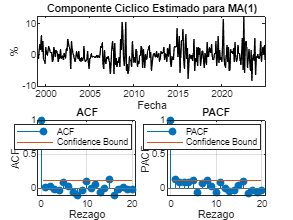

%Graficando la FAC y la PAC
    figure ()
    subplot(2,1,1)
    plot(ds_estimar.Fecha,ds_estimar.residuales_001,'Color','k')
    title('Componente Ciclico Estimado para MA(1)')
    xlabel('Fecha') 
    ylabel('%') 
        
     subplot(2,2,3)
     autocorr(ds_estimar.residuales_001)
     ylabel('ACF')
     xlabel('Rezago')
     title('ACF')
        
     subplot(2,2,4)
     parcorr(ds_estimar.residuales_001_2)
     ylabel('PACF')
     xlabel('Rezago')
     title('PACF')
     saveas(gcf,'ARIMA_001_rezagos.png');

% Probando dinámicas de varianza condicional (Con el ARIMA(0,0,1)),
[h2,P_Value2,Estadistico2,Valor_Critico2] = lbqtest(ds_estimar.residuales_001_2(1:191,:),'lags',[5,10,15])

h2 = 1×3 logical array
   1   1   1


P_Value2 = 1.0e-05 *

    0.0343    0.0634    0.6729


Estadistico2 =    38.2055   47.9495   51.5397


Valor_Critico2 =    11.0705   18.3070   24.9958



P_Value2=[P_Value2]';
Estadistico2=[Estadistico2]';
Valor_Critico2=[Valor_Critico2]';

R1 = {'5 Rezagos';'10 Rezagos'; '15 Rezagos'};

Estadistico_Q2=table(P_Value2,Estadistico2,Valor_Critico2,'RowNames',R1)

Estadistico_Q2 = 3×3 table
                   P_Value2     Estadistico2    Valor_Critico2
                  __________    ____________    ______________

    5 Rezagos      3.431e-07       38.206            11.07    
    10 Rezagos    6.3399e-07       47.949           18.307    
    15 Rezagos    6.7287e-06        51.54           24.996    



writetable(Estadistico_Q2, 'Ljung-Box_cuadrado_2.xlsx', 'WriteRowNames', true)

%Como el p-valor es bajo, se rechaza H0, indicando que los cuadrados de los residuos sí se
%autocorrelacionan). Si hay heteroscedasticidad condicional, si es
%necesario modelar la varianza

%Incorporando dinámicas de varianza con un GARCH(1,1),
Mdl4 = arima('ARLags', [], 'MALags', 1, 'D', 0, 'Constant', 0, 'Variance', garch(1,1));
[EstMdl4,] = estimate(Mdl4,ds_estimar.Colombia);

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.35915      0.055359         6.4877      8.7161e-11

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.49215       0.22129          2.224         0.02615
    GARCH{1}    0.72555      0.053848         13.

error_4= infer(EstMdl4,ds_estimar.Colombia);
ds_estimar.error_4= [infer(EstMdl4,ds_estimar.Colombia)];
ds_estimar.e4_2=ds_estimar.error_4.^2; %MA(1)

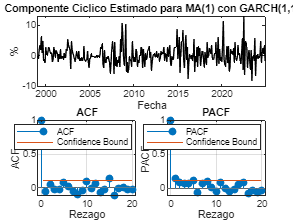

Unrecognized function or variable 'EstMdl3'.

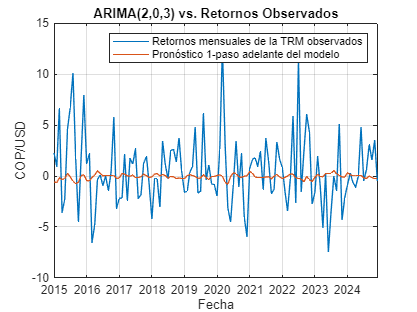

%Graficando la FAC y la PAC
    figure ()
    subplot(2,1,1)
    plot(ds_estimar.Fecha,ds_estimar.error_4,'Color','k')
    title('Componente Ciclico Estimado para MA(1) con GARCH(1,1)')
    xlabel('Fecha') 
    ylabel('%') 
        
     subplot(2,2,3)
     autocorr(ds_estimar.error_4)
     ylabel('ACF')
     xlabel('Rezago')
     title('ACF')
        
     subplot(2,2,4)
     parcorr(ds_estimar.e4_2)
     ylabel('PACF')
     xlabel('Rezago')
     title('PACF')
     saveas(gcf,'MA_1_GARCH_rezagos.png');

%Construyendo la gráfica del pronóstico punto del MA(1) GARCH(1,1),
f2=[];
S2=[];

parfor i= 0:119 
%Estimación Modelo    
[Mdl2,] = estimate(Mdl4,ds_estimar.Colombia(1:192+i)); 

% pronostico 1 paso adelante:
[TDf2,~] = forecast(EstMdl4,1,'Y0',ds_estimar.Colombia(1:192+i));

% 1000 simulaciones por cada pronostico 1 paso adelante:
[simulacion2,] = simulate(EstMdl4,1,'NumPaths',1000, 'Y0',ds_estimar.Colombia(1:192+i));

%Guardando el pronóstico y las simulaciones:
f2(i+1,:)=TDf2;
S2(i+1,:)=simulacion2;
end

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.35915      0.055359         6.4877      8.7161e-11

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.49215       0.22129          2.224         0.02615
    GARCH{1}    0.72555      0.053848         13.

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic     PValue  
                _______    _____________    __________    _________

    Constant          0             0            NaN            NaN
    MA{1}       0.39442      0.055573         7.0974      1.271e-12

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.51848       0.24374         2.1272        0.033405
    GARCH{1}    0.67815      0.065206           10.4 

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.40079       0.05539         7.2357      4.6299e-13

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.52897       0.24751         2.1372        0.032584
    GARCH{1}    0.67362       0.06598          10

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.40763       0.05521         7.3834      1.5432e-13

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     0.5397       0.25131         2.1475        0.031751
    GARCH{1}    0.66903      0.066778         10.

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.40531      0.087987         4.6065      4.0952e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.47874       0.19253         2.4866        0.012898
    GARCH{1}    0.59784      0.086332         6.9

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                Value     StandardError    TStatistic      PValue  
                ______    _____________    __________    __________

    Constant         0             0            NaN             NaN
    MA{1}       0.4099      0.088212         4.6468      3.3711e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant      0.472       0.19349         2.4394        0.014711
    GARCH{1}    0.60581      0.088345         6.8573 

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.41273      0.088253         4.6766      2.9165e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic     PValue  
                _______    _____________    __________    _________

    Constant    0.46367       0.19344          2.397       0.016529
    GARCH{1}    0.61306      0.089989         6.8126

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.41575      0.088282         4.7093      2.4852e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.44444       0.19353         2.2965        0.021645
    GARCH{1}    0.62853      0.093817         6.6

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.41809      0.088258         4.7372      2.1669e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.42971       0.19372         2.2182        0.026541
    GARCH{1}    0.64014       0.09621         6.6

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic     PValue  
                _______    _____________    __________    _________

    Constant          0             0            NaN            NaN
    MA{1}       0.41974      0.088248         4.7564      1.971e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.42089       0.19405         2.1689        0.030087
    GARCH{1}    0.64734      0.097378         6.6477 

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                Value     StandardError    TStatistic     PValue  
                ______    _____________    __________    _________

    Constant         0             0            NaN            NaN
    MA{1}       0.4204      0.088293         4.7615      1.922e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.42005        0.1946         2.1585        0.030886
    GARCH{1}    0.64871       0.09761         6.6459     

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0           NaN              NaN
    MA{1}       0.41911      0.088421          4.74       2.1374e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.42674       0.19559         2.1818        0.029125
    GARCH{1}     0.6446      0.097397         6.6

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.42894      0.089062         4.8162      1.4634e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.44282       0.19836         2.2324         0.02559
    GARCH{1}    0.63204      0.096985         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.43144      0.089059         4.8444      1.2697e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.44046       0.19874         2.2163        0.026673
    GARCH{1}    0.63437      0.097453         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.43029      0.089165         4.8258      1.3943e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.44434       0.19944          2.228         0.02588
    GARCH{1}    0.63226      0.097238         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.42221      0.090058         4.6882      2.7558e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.45109       0.19912         2.2654        0.023488
    GARCH{1}    0.62609      0.095965         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0           NaN              NaN
    MA{1}       0.42306      0.090052         4.698       2.6273e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.45006       0.19934         2.2577        0.023963
    GARCH{1}    0.62722      0.096202         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.41861      0.090411         4.6301      3.6543e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     0.4511       0.19935         2.2629        0.023642
    GARCH{1}    0.62641      0.095968         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.41752      0.090519         4.6126      3.9771e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.45896        0.2004         2.2902        0.022007
    GARCH{1}    0.62158      0.095409          6.

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.41379      0.090785         4.5579      5.1662e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.45689        0.1991         2.2947        0.021749
    GARCH{1}    0.62117      0.095114         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic     PValue  
                _______    _____________    __________    _________

    Constant          0             0            NaN            NaN
    MA{1}       0.40933      0.091113         4.4926      7.037e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.45805       0.19888         2.3032        0.021268
    GARCH{1}    0.61988      0.094747         6.5425 

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.40385      0.091559         4.4109      1.0296e-05

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.45976       0.19868         2.3141         0.02066
    GARCH{1}    0.61814      0.094281         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.40503      0.091688         4.4175      9.9842e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.46561       0.19979         2.3305        0.019782
    GARCH{1}    0.61505      0.093978         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.41361      0.091983         4.4966      6.9037e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.46179       0.19976         2.3117        0.020795
    GARCH{1}    0.61821      0.094739         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.40382      0.093222         4.3319      1.4785e-05

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.46853       0.19923         2.3517        0.018686
    GARCH{1}    0.61117      0.093023         6.5

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          0             0            NaN             NaN
    MA{1}       0.40477      0.093348         4.3361      1.4501e-05

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.47252       0.20022           2.36        0.018276
    GARCH{1}    0.60941      0.092859         6.5


% Veamos que tan buenos fueron Visualmente los pronosticos:
ds_estimar.f2=[NaN(191,1); f2];


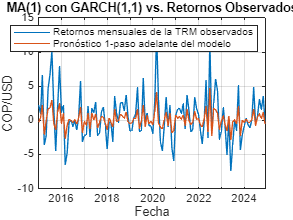

%%Construyendo la gráfica del pronóstico punto,
figure()
plot(ds_estimar.Fecha(192:end), ds_estimar.Colombia(192:end), ...
     ds_estimar.Fecha(192:end), ds_estimar.f2(192:end))
title('MA(1) con GARCH(1,1) vs. Retornos Observados')
xlabel('Fecha')
ylabel('COP/USD')
legend('Retornos mensuales de la TRM observados', "Pronóstico 1-paso adelante del modelo")
grid on

saveas(gcf,'Pronostico_punto_MA1GARCH11.png');

%2) Estimando el modelo incluyendo el componente principal,
%Usando el factor que estimamos antes para construir la matriz XX,
XX=[ones(T,1) PC(1:T,1)];

Mdl5 = arima('ARLags', [], ...
             'MALags', 1, ...
             'D', 0, ...
             'Constant', 0, ...
             'Beta', NaN(2,1), ...  % <-- Aquí defines que hay 2 regresores
             'Variance', garch(1,1));

%Estimando el modelo MA(1) GARCH(1,1) con el componente principal 
[Modelo_final,~] = estimate(Mdl5,ds_estimar.Colombia(1:191,:),'X',XX);

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________


error_final= infer(Modelo_final,ds_estimar.Colombia);
ds_estimar.error_final= [infer(Modelo_final,ds_estimar.Colombia)];

%1) Realizando el pronóstico punto de enero de 2015 hasta diciembre de 2024 (192-311),
%Para el ARIMAX,
f3=[];
S3=[];
N= height(ds_estimar);

parfor i= 0:119
%Estimación Modelo    
[Modelo_final,~] = estimate(Mdl5,ds_estimar.Colombia(1:191,:),'X',XX);
% pronostico 1 paso adelante:
[TDf3,~] = forecast(Modelo_final,1,'Y0',ds_estimar.Colombia(1:192+i));

% 1000 simulaciones por cada pronostico 1 paso adelante:
[simulacion_final,] = simulate(Modelo_final,1,'NumPaths',1000, 'Y0',ds_estimar.Colombia(1:192+i));

%Guardando el pronóstico y las simulaciones:
f3(i+1,:)=TDf3;
S3(i+1,:)=simulacion_final;
end

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________

 
    ARIMAX(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0             NaN            NaN
    MA{1}          0.41386      0.093161          4.4425     8.8937e-06
    Beta(1)     -0.0083087       0.19799       -0.041965        0.96653
    Beta(2)       -0.10501      0.064834         -1.6198        0.10528

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________


% Veamos que tan buenos fueron Visualmente los pronosticos:
ds_estimar.f3=[NaN(191,1); f3];

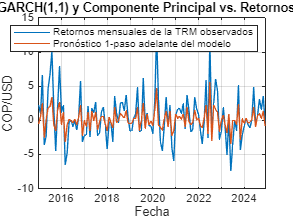

%%Construyendo la gráfica del pronóstico punto,
figure()
plot(ds_estimar.Fecha(192:end), ds_estimar.Colombia(192:end), ...
     ds_estimar.Fecha(192:end), ds_estimar.f3(192:end))
title('MA(1) con GARCH(1,1) y Componente Principal vs. Retornos Observados')
xlabel('Fecha')
ylabel('COP/USD')
legend('Retornos mensuales de la TRM observados', "Pronóstico 1-paso adelante del modelo")
grid on

saveas(gcf,'Pronostico_punto_arimax.png');

%3) Comparando los estándares relativos,
%Medidas de precisión de los pronosticos para el modelo MA(1) GARCH (1,1) y
%el ARIMAX

% estimemos los errores al cuadrado:
ds_estimar.e4_2=ds_estimar.error_4.^2; %MA(1)
ds_estimar.efinal_2=ds_estimar.error_final.^2; %ARIMAX

% errores medios al cuadrado:
MSE1=nanmean(ds_estimar.e4_2);
MSE2=nanmean(ds_estimar.efinal_2);

% RMSE
RMSE1=sqrt(MSE1);
RMSE2=sqrt(MSE2);

%MAE
ds_estimar.e4_A=abs(ds_estimar.error_4);
ds_estimar.efinal_A=abs(ds_estimar.error_final);

MAE1=nanmean(ds_estimar.e4_A);
MAE2=nanmean(ds_estimar.efinal_A);

%R Cuadrado Predictivo
MuTD=mean(ds_estimar.Colombia(192:end))

MuTD = 0.5221

ETD_2=(ds_estimar.Colombia(192:end)-MuTD).^2;
Denominador1=sum(ETD_2);

R_2P1 = 1 - (nansum(ds_estimar.e4_2(192:end))     / Denominador1);
R_2P2 = 1 - (nansum(ds_estimar.efinal_2(192:end)) / Denominador1);

%Comparando con una caminata aleatoria,
%Estimando una caminata aleatoria,
%Pronóstico punto:
ds_estimar.f_rw=[NaN(191,1); ds_estimar.Colombia(191:end-1)];

%Errores pronóstico:
ds_estimar.error_rw = ds_estimar.Colombia - ds_estimar.f_rw;

%Creando los errores de pronóstico al cuadrado,
ds_estimar.e_rw_2=ds_estimar.error_rw.^2;

% U-THEIL
U1 = 1 - (nansum(ds_estimar.e4_2(192:end))     / nansum(ds_estimar.e_rw_2(192:end)));
U2 = 1 - (nansum(ds_estimar.efinal_2(192:end)) / nansum(ds_estimar.e_rw_2(192:end)));

% Tabla resumen resultados:

MSE=[MSE1; MSE2];
RMSE=[RMSE1; RMSE2];
MAE=[MAE1; MAE2];
R2_P=[R_2P1; R_2P2];
U=[U1; U2];

R2 = {'MA(1) con GARCH(1,1)';'MA(1) con GARCH(1,1) y Componente Principal'};

Criterios=table(MSE,RMSE,MAE, R2_P, U,'RowNames',R2)

Criterios = 2×5 table
                                                    MSE      RMSE      MAE        R2_P          U   
                                                   ______    _____    ______    _________    _______

    MA(1) con GARCH(1,1)                           8.8923    2.982     2.191    -0.045409    0.42564
    MA(1) con GARCH(1,1) y Componente Principal    8.9882    2.998    2.1953    -0.075854    0.40891



%Exportando la tabla,
writetable(Criterios, 'Estandares_relativos.xlsx', 'WriteRowNames', true);